## FA4 strain

modelName = 'FA234';
open_system(modelName)
set_param(modelName + "/Manual Switch1",'sw','1')

set_param(modelName + "/Manual Switch2",'sw','1')
set_param(modelName + "/Model selection (manual)",'Value','2') % FA4 model

set_param(modelName + "/Manual Switch3",'sw','0')
load("optInput_FA4.mat")
set_param(modelName + "/To test manually",'Value', num2str(optInput(1).Value)) % optimum for FA3

mdlWks = get_param(modelName,'ModelWorkspace');
k_E_nom = getVariable(mdlWks,'k_E');

spv_length = 100;
setPointValues = linspace(0,2,spv_length)*k_E_nom; % k_E

for i = 1:1:spv_length
    in(i) = Simulink.SimulationInput(modelName);
    in(i) = in(i).setVariable('k_E',setPointValues(i),'Workspace',modelName);
end

out{3} = sim(in,'ShowSimulationManager','on','ShowProgress','on')

[10-Nov-2023 22:42:48] シミュレーションの実行中...
[10-Nov-2023 22:42:50] シミュレーション実行 1/100 が完了
[10-Nov-2023 22:42:51] シミュレーション実行 2/100 が完了
[10-Nov-2023 22:42:52] シミュレーション実行 3/100 が完了
[10-Nov-2023 22:42:53] シミュレーション実行 4/100 が完了
[10-Nov-2023 22:42:54] シミュレーション実行 5/100 が完了
[10-Nov-2023 22:42:54] シミュレーション実行 6/100 が完了
[10-Nov-2023 22:42:55] シミュレーション実行 7/100 が完了
[10-Nov-2023 22:42:56] シミュレーション実行 8/100 が完了
[10-Nov-2023 22:42:57] シミュレーション実行 9/100 が完了
[10-Nov-2023 22:42:57] シミュレーション実行 10/100 が完了
[10-Nov-2023 22:42:58] シミュレーション実行 11/100 が完了
[10-Nov-2023 22:42:59] シミュレーション実行 12/100 が完了
[10-Nov-2023 22:43:00] シミュレーション実行 13/100 が完了
[10-Nov-2023 22:43:01] シミュレーション実行 14/100 が完了
[10-Nov-2023 22:43:02] シミュレーション実行 15/100 が完了
[10-Nov-2023 22:43:02] シミュレーション実行 16/100 が完了
[10-Nov-2023 22:43:03] シミュレーション実行 17/100 が完了
[10-Nov-2023 22:43:04] シミュレーション実行 18/100 が完了
[10-Nov-2023 22:43:05] シミュレーション実行 19/100 が完了
[10-Nov-2023 22:43:05] シミュレーション実行 20/100 が完了
[10-Nov-2023 22:43:06] シミュレーション実行 21/100 が完了
[10-Nov-2023 22:43:07] シミ

out = 1×3 の cell 配列
    {0×0 double}    {0×0 double}    {1×100 Simulink.SimulationOutput}


FFA_end = zeros(spv_length,4);
FFA_end(:,1) = setPointValues;
for i = 1:1:spv_length
    FFA_end(i,4) = out{3}(i).logsout{1}.Values.Data(end);
end

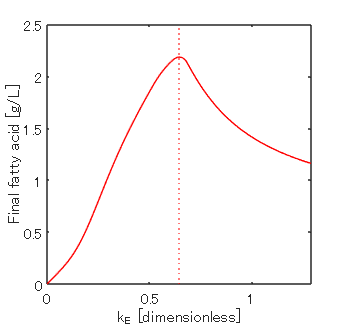

figure('Position', [120 120 250 240]);
plot(FFA_end(:,1),FFA_end(:,4),'r-')
xline(k_E_nom,'r:')
xlim([0 k_E_nom*2])
ylim([0 2.5])
xlabel('k_E [dimensionless]')
% xticks([1 10 40 100 400 1000])
% yticks([0 20 40 60 80])
ylabel('Final fatty acid [g/L]')
set(gca,'xscale','linear')

## FA3 strain

set_param(modelName + "/Manual Switch1",'sw','1')

set_param(modelName + "/Manual Switch2",'sw','1')
set_param(modelName + "/Model selection (manual)",'Value','1') % FA3 model

set_param(modelName + "/Manual Switch3",'sw','0')
load("optInput_FA3.mat")
set_param(modelName + "/To test manually",'Value', num2str(optInput(1).Value)) % optimum for FA3

out{2} = sim(in,'ShowSimulationManager','on','ShowProgress','on')

[10-Nov-2023 22:44:15] シミュレーションの実行中...
[10-Nov-2023 22:44:16] シミュレーション実行 1/100 が完了
[10-Nov-2023 22:44:16] シミュレーション実行 2/100 が完了
[10-Nov-2023 22:44:17] シミュレーション実行 3/100 が完了
[10-Nov-2023 22:44:18] シミュレーション実行 4/100 が完了
[10-Nov-2023 22:44:19] シミュレーション実行 5/100 が完了
[10-Nov-2023 22:44:20] シミュレーション実行 6/100 が完了
[10-Nov-2023 22:44:21] シミュレーション実行 7/100 が完了
[10-Nov-2023 22:44:22] シミュレーション実行 8/100 が完了
[10-Nov-2023 22:44:23] シミュレーション実行 9/100 が完了
[10-Nov-2023 22:44:23] シミュレーション実行 10/100 が完了
[10-Nov-2023 22:44:24] シミュレーション実行 11/100 が完了
[10-Nov-2023 22:44:25] シミュレーション実行 12/100 が完了
[10-Nov-2023 22:44:26] シミュレーション実行 13/100 が完了
[10-Nov-2023 22:44:27] シミュレーション実行 14/100 が完了
[10-Nov-2023 22:44:28] シミュレーション実行 15/100 が完了
[10-Nov-2023 22:44:29] シミュレーション実行 16/100 が完了
[10-Nov-2023 22:44:30] シミュレーション実行 17/100 が完了
[10-Nov-2023 22:44:31] シミュレーション実行 18/100 が完了
[10-Nov-2023 22:44:32] シミュレーション実行 19/100 が完了
[10-Nov-2023 22:44:33] シミュレーション実行 20/100 が完了
[10-Nov-2023 22:44:34] シミュレーション実行 21/100 が完了
[10-Nov-2023 22:44:35] シミ

out = 1×3 の cell 配列
    {0×0 double}    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}


for i = 1:1:spv_length
    FFA_end(i,3) = out{2}(i).logsout{1}.Values.Data(end);
end

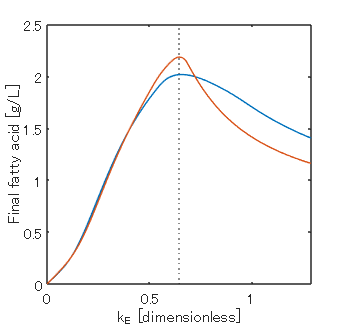

figure('Position', [120 120 250 240]);
plot(FFA_end(:,1),FFA_end(:,[3 4]),'-')
xline(k_E_nom,':')
xlim([0 k_E_nom*2])
ylim([0 2.5])
xlabel('k_E [dimensionless]')
% xticks([1 10 40 100 400 1000])
% yticks([0 20 40 60 80])
ylabel('Final fatty acid [g/L]')
set(gca,'xscale','linear')

## FA2 strain

set_param(modelName + "/Manual Switch1",'sw','1')

set_param(modelName + "/Manual Switch2",'sw','1')
set_param(modelName + "/Model selection (manual)",'Value','0') % FA2 model

set_param(modelName + "/Manual Switch3",'sw','0')

load("optInput_FA2.mat")
set_param(modelName + "/To test manually",'Value', num2str(optInput(1).Value)) % optimum for FA2

out{1} = sim(in,'ShowSimulationManager','on','ShowProgress','on')

[10-Nov-2023 22:45:50] シミュレーションの実行中...
[10-Nov-2023 22:45:51] シミュレーション実行 1/100 が完了
[10-Nov-2023 22:45:52] シミュレーション実行 2/100 が完了
[10-Nov-2023 22:45:53] シミュレーション実行 3/100 が完了
[10-Nov-2023 22:45:54] シミュレーション実行 4/100 が完了
[10-Nov-2023 22:45:55] シミュレーション実行 5/100 が完了
[10-Nov-2023 22:45:56] シミュレーション実行 6/100 が完了
[10-Nov-2023 22:45:57] シミュレーション実行 7/100 が完了
[10-Nov-2023 22:45:58] シミュレーション実行 8/100 が完了
[10-Nov-2023 22:45:59] シミュレーション実行 9/100 が完了
[10-Nov-2023 22:46:00] シミュレーション実行 10/100 が完了
[10-Nov-2023 22:46:01] シミュレーション実行 11/100 が完了
[10-Nov-2023 22:46:02] シミュレーション実行 12/100 が完了
[10-Nov-2023 22:46:03] シミュレーション実行 13/100 が完了
[10-Nov-2023 22:46:03] シミュレーション実行 14/100 が完了
[10-Nov-2023 22:46:04] シミュレーション実行 15/100 が完了
[10-Nov-2023 22:46:06] シミュレーション実行 16/100 が完了
[10-Nov-2023 22:46:07] シミュレーション実行 17/100 が完了
[10-Nov-2023 22:46:08] シミュレーション実行 18/100 が完了
[10-Nov-2023 22:46:09] シミュレーション実行 19/100 が完了
[10-Nov-2023 22:46:09] シミュレーション実行 20/100 が完了
[10-Nov-2023 22:46:10] シミュレーション実行 21/100 が完了
[10-Nov-2023 22:46:11] シミ

out = 1×3 の cell 配列
    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}


for i = 1:1:spv_length
    FFA_end(i,2) = out{1}(i).logsout{1}.Values.Data(end);
end

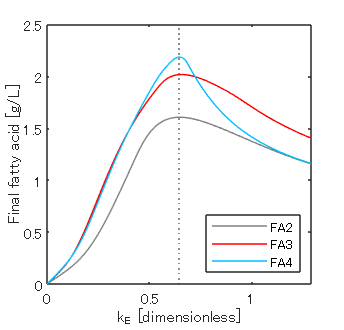

figure('Position', [120 120 250 240]);
plot(FFA_end(:,1),FFA_end(:,2:4),'-')
xline(k_E_nom,':')
xlim([0 k_E_nom*2])
ylim([0 2.5])
xlabel('k_E [dimensionless]')
% xticks([1 10 40 100 400 1000])
% yticks([0 20 40 60 80])
ylabel('Final fatty acid [g/L]')
set(gca,'xscale','linear')
colororder(["#808080";"r";"#00bfff"])
legend('FA2','FA3','FA4','Location','southeast')